# **Circuitos Electricos II**

**Roberto Sanchez Figueroa**

**brrsanchezfi@unal.edu.co**

***Monitoria Circuitos II***

***GIT-HUB:  ***[***https://github.com/brrsanchezfi/Circuitos_2022_1***](https://github.com/brrsanchezfi/Circuitos_2022_1)

# **Soluciones propuestas para los ejercicios del taller 5**

## ***Ejercicio 1 (bode sintotico de manera "manual") e implementacion del algoritmo "asymp" ***

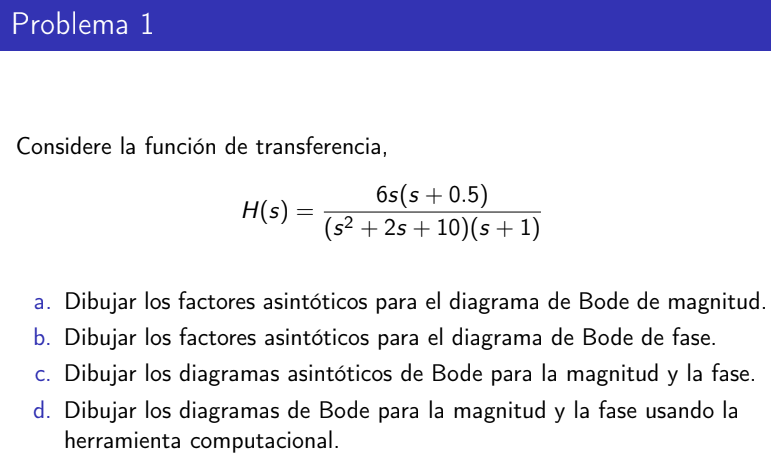


$$H(s)=\frac{6 s(s+0.5)}{\left(s^{2}+2 s+10\right)(s+1)}$$


$H\left(s\right)=\frac{6}{10}\;\;s\;\left(\frac{10\;\;\;}{s^2 +2s+10}\right)\;\left(s+5\right)\left(\frac{1}{s+1}\right)$   NOTE QUE TENEMOS LOS SIGUIENTE TERMINOS

### Constante K

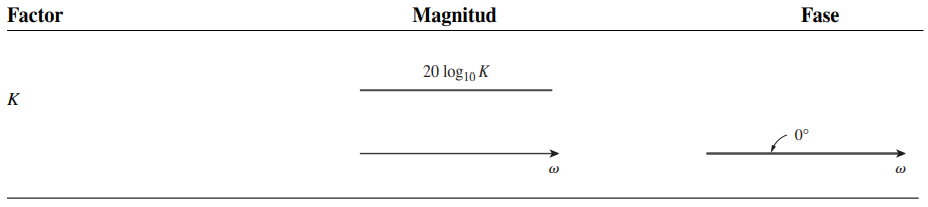

$20\log \left(\frac{6}{10}\right)=-4\ldotp 43\textrm{db}$  de senal estatica funciona como un offset para el resto de funciones 

### Cero en el origen

$s$  es un 'Z'ero simple, por tanto aplicamos la siguiente condicion,*** SIEMPRE PASA POR EL ORIGEN ***

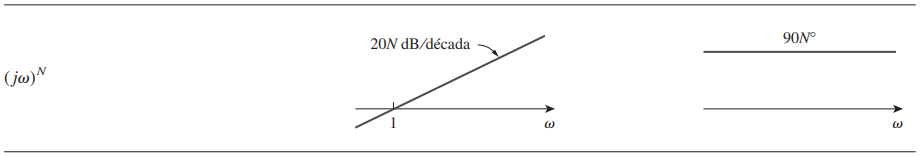

fuente = [https://lpsa.swarthmore.edu/Bode/BodeHow.html,](https://lpsa.swarthmore.edu/Bode/BodeHow.html,) y sadiku.

$\begin{array}{l}
j\omega^N =s^N \\
\\
20\log \left(\omega^N \right)\\
\\
N*20\log \left(\omega \right)
\end{array}$      esta es otra manera de verlo.

### Polo complejo

El polo complejo es aquel polinomio de grado dos que sus raices son complejas, por tanto la solucion **'NO'** es descomponerla en raices complejas, aun que algebraicamente es viable no es practica por tanto usamos la siguiente condicion

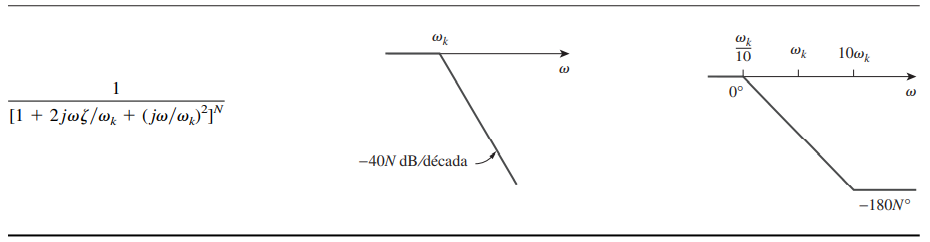

Es normal ver esta exprecion y no identificarla, no obstante se debe ver de la siguiente manera de una forma mas sencilla pero igualmente equivalente


$$j\omega =s$$



$$\frac{{\omega_n }^2 }{s^2 +2\zeta \omega_n s+{\omega_n }^2 }$$
 

$\left(\frac{10\;\;\;}{s^2 +2\zeta \sqrt{10}s+10}\right)$   por tanto $\begin{array}{l}
\omega_n^2 =10\\
\omega_n =\sqrt{10}
\end{array}$

### Cero simple

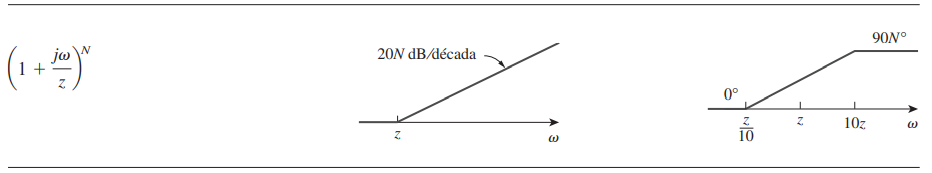


$${\left(s+0\ldotp 5\right)}$$



$$\omega_n =0\ldotp 5$$


### Polo simple

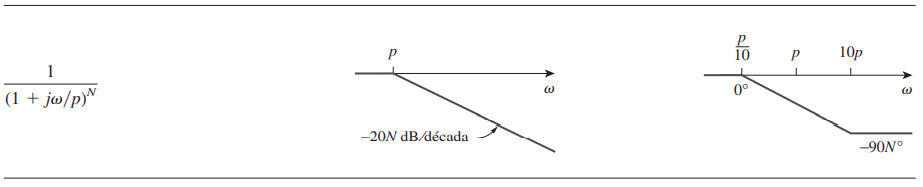


$$\left(\frac{1}{s+1}\right)$$



$$\omega_n =1$$


PRESENTACION GRAFICA

se hace el trazado de las asintotas sobre el plot generado con matlab para contrastar

h = tf([6 3 0],[conv([1 2 10],[1 1])])

h =
 
        6 s^2 + 3 s
  -----------------------
  s^3 + 3 s^2 + 12 s + 10
 
Continuous-time transfer function.



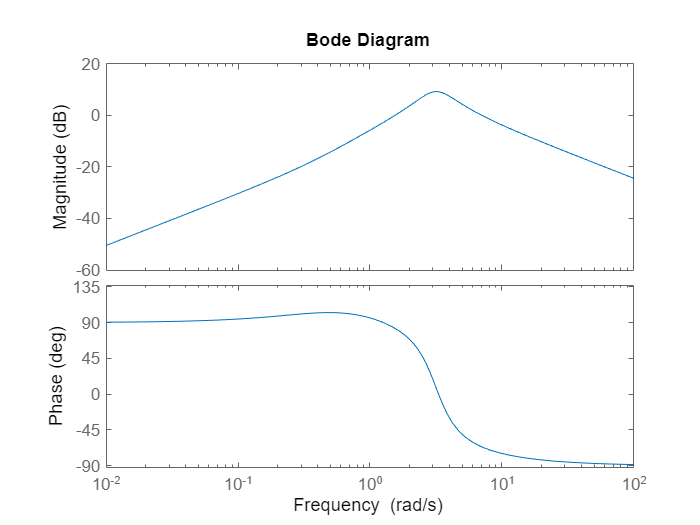

bode(h)

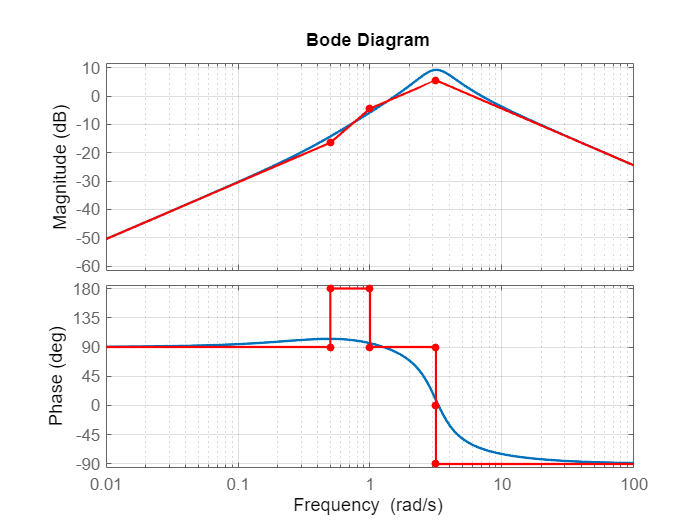

asymp(h)

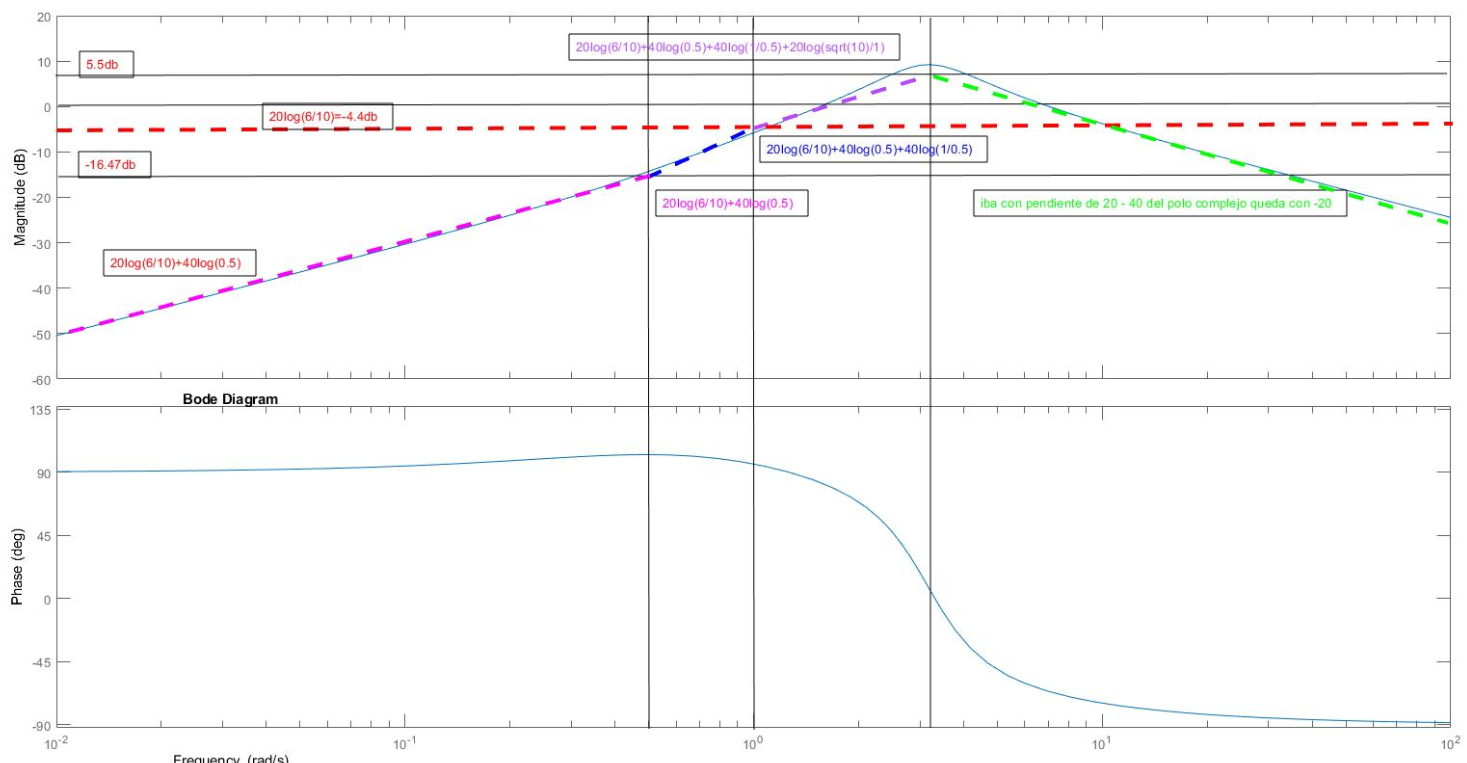

## Ejercicio 2, Aplicacion del matlab simbolico y asymp

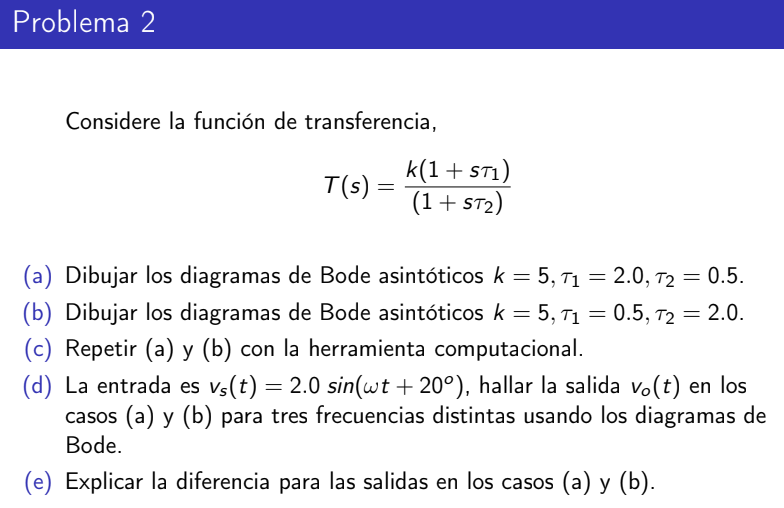

%variables punto a b
k = 5;
t1_1=2;
t1_2=0.5;
t2_1=0.5;
t2_2=2;

%a)bode asintotico usando asymp
H_a = tf([k*t1_1 k*1],[t1_2 1])

H_a =
 
  10 s + 5
  ---------
  0.5 s + 1
 
Continuous-time transfer function.



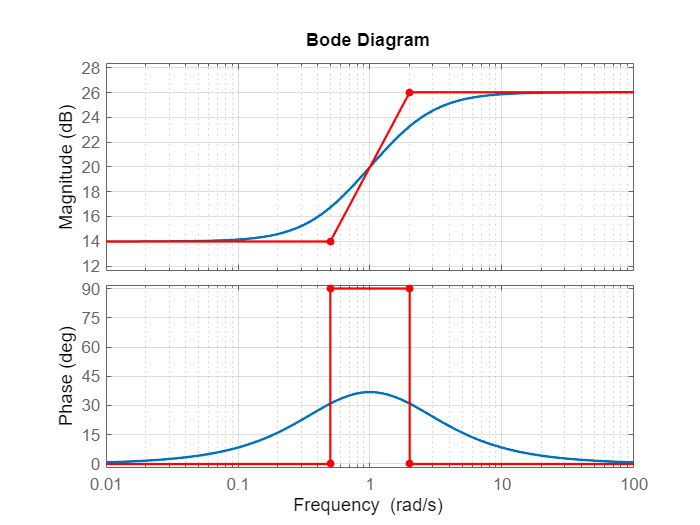

asymp(H_a)

%b)bode asintotico usando asymp
H_b = tf([k*t2_1 k*1],[t2_2 1])

H_b =
 
  2.5 s + 5
  ---------
   2 s + 1
 
Continuous-time transfer function.



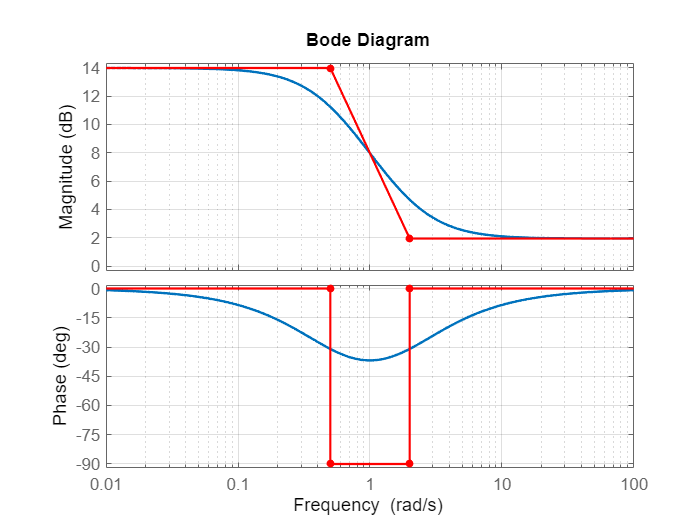

asymp(H_b)

%C. se omite

%d. consideramos una rfecuencia w de 100

     

$H\left(s\right)=\frac{V_o \left(s\right)}{V_s \left(s\right)}$     Despejamos $V_o \left(s\right)$ 

    w=100;
    angulo = 20;
    tiempo= linspace(0,0.5,1000);%tiempo
    v_s_n = 2*sin(w*tiempo+angulo);%  funcion numero


Como utilizar el diagrama de bode para calcular la respuesta del sistema

- nos plantamos en la frecuencia del sistema y procedemos a tomar la ganacia y fas.

- convertimos la escala de ganancia de decibeles a una ganancia lineal, esa es la amplitud de nuestra senal

- y por ultimo sumamos o restamos los grados necesario a nuestra senal de entrada

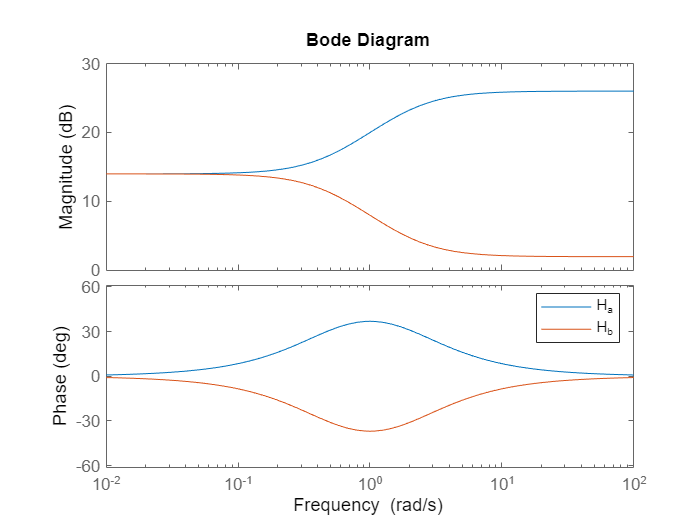

 bode(H_a, H_b)
 legend(["H_a";"H_b"])

Comparando la magnitud con la tabla tomada del libro de sadiku notamos lo siguiente

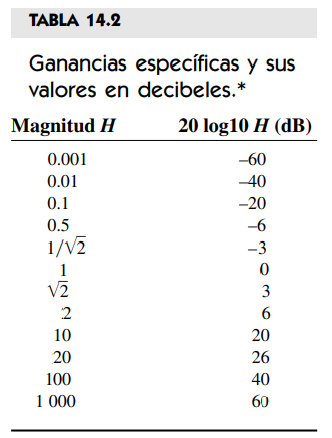

Recordemos que nuestra senal de salida es 


$$v_s \left(t\right)=2\;\sin \left(\omega t+{20}^o \right)$$


Por lo tanto tenemos una una ganacia de 26db que pasado a una escala lineal corresponde a una ganancia de 20 y un desfase de 0 grados por tanto nuestra senal queda de la siguiente form. 

$20*\left(2\sin \left(\omega t+{20}^o +0^o \right)\right)=40\sin \left(\omega t+{20}^o \right)$   para la funcion de tranferencia A

Para la funcion de tranferencia B tenemos una ganancia de 1.94db que pasad a lineal corresponde a 1.25  y un desface de 0 grados,igual que en el anterior ejemplo tenemos que:

 $1\ldotp 25*\left(2\sin \left(\omega t+{20}^o +0^o \right)\right)=2\ldotp 5\sin \left(\omega t+{20}^o \right)$   para la funcion de tranferencia B

Procedemos a plotear las graficas 

 salida_a = 40*sin(w.*tiempo+angulo);
 salida_b = 2.5*sin(w.*tiempo+angulo);

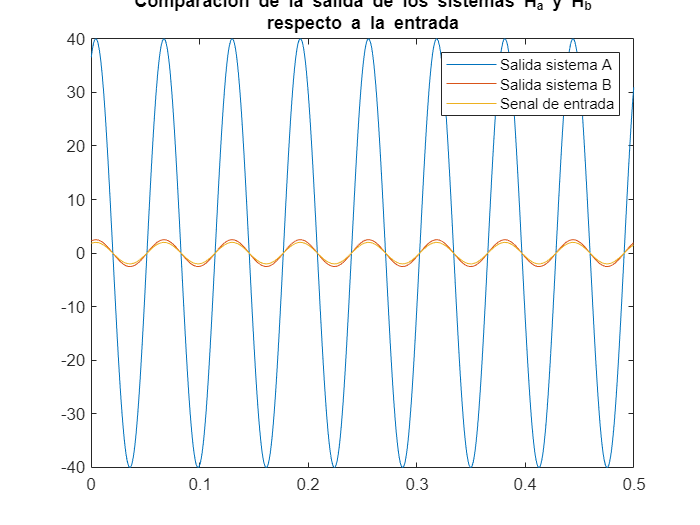

 plot(tiempo,salida_a,tiempo,salida_b,tiempo,v_s_n)
 legend(["Salida sistema A";"Salida sistema B";"Senal de entrada"])
 title(["Comparacion de la salida de los sistemas H_a y H_b";"respecto a la entrada"])

## Simulacion

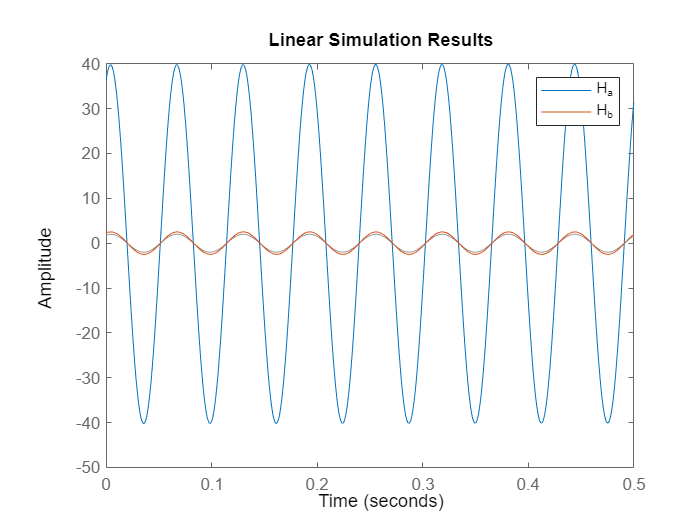

 lsim(H_a,H_b,v_s_n,tiempo)           %comando lsim simula una funcion de entrada con una funcion de transferencia
 legend(["H_a"; "H_b"])

## Conclusiones

- Una de las utlidades mas importantes de los diagramas de bode es describir el comportamiento de los sistemas en funcion de su frecuencia.

- Los diagramas de bode asintoticos permite constuir y entender la informacion que proporciona una funcion de transferencia.

- Matlab tiene una cantidad de librerias y herramientas para la solucion de estos problemas, no obstante es importante tener conceptos claros.

## Referencias

- C,K Alexander,M.O Sadiku, "Fundamentos de Circuitos Eléctricos". Edición. 5 Cleveland: MC Graw Hill, 2006.

- Canal youtube "Brian Douglas"  [https://www.youtube.com/channel/UCq0imsn84ShAe9PBOFnoIrg](https://www.youtube.com/channel/UCq0imsn84ShAe9PBOFnoIrg) , Material interesante acerca de bodes en Ingles.

## Herramientas interesantes

funciones que sirven para pasar de tf a symbolico y viceversa, muy utiles para trabajar con laplace, muy recomendadas.

function t_sym = tf2sym(H)
       [num,den] = tfdata(H);
       syms s;
       t_sym = simplify(poly2sym(cell2mat(num),s)/poly2sym(cell2mat(den),s));
end

function [ tfobj ] = sym2tf( symobj, Ts) %pasa de sym a tf    Ts es el samplin, para continuas dejar en 0
    % SYM2TF convert symbolic math rationals to transfer function
    
    if isnumeric(symobj)
        tfobj=symobj;
        return;
    end
    
    [n,d]=numden(symobj);
    num=sym2poly(n);
    den=sym2poly(d);
    
    if nargin==1
        tfobj=tf(num,den);
    else
        tfobj=tf(num,den,Ts);
    end
end